# Assignment 10 

# Development of a tracking filter of a moving object when measurements and motion

# models are in different coordinate systems

By 

Group 19 

Ahmed Baza, Skoltech, 2020

Ahmed Elgohary, Skoltech, 2020

Mohammed Sayed, Skoltech, 2020

Ziad Baraka, Skoltech, 2020

1.Generate a true trajectory $X_{i\;}$ of an object that moves uniformly. Trajectory is deterministic,as no random disturbance affect a motion.

2. Generate also true values of range D and azimuth β

3. Generate measurements D m and βm of range D and azimuth β

4. Transform polar coordinates Dm and βm to Cartesian ones and get pseudo-measurements of coordinates x and y

5. Create the measurement vector z from pseudo-measurements of coordinates x and y

6. define initial conditions for Kalman filter algorithm

7. Create the transition matrix Φ and observation matrix H

8. Create the measurement error covariance matrix R needed for Kalman filter algorithm

9. Develop Kalman filter algorithm to estimate state vector X i (extrapolation and filtration)

10.  Run Kalman filter algorithm over M  =  500 runs.

close all;
clear;

m = 1;    %Extrapolation steps
N = 26;   %Number of points
NE = N-m; %Number of points for the extrapolation error

Errx = zeros(500,N);          %X true estimation error
ErrxE = zeros(500,NE);        %X-extrapolated true estimation error
Erry = zeros(500,N);          %Y true estimation error
ErryE = zeros(500,NE);        %Y-extrapolated true estimation error
ErrD = zeros(500,N);          %D true estimation error
ErrDE = zeros(500,NE);        %D-extrapolated true estimation error
Errbeta = zeros(500,N);       %beta true estimation error
ErrbetaE = zeros(500,NE);     %beta-extrapolated true estimation error


% Run Kalman filter algorithm over M  =  500 runs.
for M = 1:500

    X = zeros(1,N);           % X-position
    Y = zeros(1,N);           % Y-position
    X(1) = 13500/sqrt(2);      % X initial value
    Y(1) = 13500/sqrt(2);      % Y initial value
    Vx = -50;     % X velocity
    Vy = -45;     % Y velocity
    T = 2;        % Time step

    D = zeros(1,N);              % Range
    beta = zeros(1,N);           % Azimuth
    D(1) = sqrt(X(1)^2+Y(1)^2);  % Range initial value
    beta(1) = atan2(X(1),Y(1));  % Azimuth initial value

    sigma_d = 20;               % Range measurements noise standard deviation
    sigma_beta = 0.02;          % Azimuth measurements noise standard deviation
    
    normaldist = makedist('Normal',0,sigma_d);
    eta_d = random(normaldist,N,1);            % Range measurements noise vector

    normaldist = makedist('Normal',0,sigma_beta);
    eta_b = random(normaldist,N,1);            % Azimuth measurements noise vector
    D_m = D;                                   % Range measurements
    beta_m = beta;                             % Azimuth measurements

    D_m(1) = D(1)+eta_d(1);                    %Range measurements initialization
    beta_m(1) = beta(1)+eta_b(1);              %Azimuth measurements initialization
    
    %Vectors generation
    for i = 2:N
        X(i) = X(i-1)+Vx*T;              % X vector generation
        Y(i) = Y(i-1)+Vy*T;              % Y vector generation
        D(i) = sqrt(X(i)^2+Y(i)^2);      % Range vector generation
        beta(i) = atan2(X(i),Y(i));      % Azimuth vector generation

        D_m(i) = D(i)+eta_d(i);          % Range measurements vector generation
        beta_m(i) = beta(i)+eta_b(i);    % Azimuth measurements vector generation
    end

    X_m = D_m.*sin(beta_m);       % X measurements vector generation    
    Y_m = D_m.*cos(beta_m);       % Y measurements vector generation

    Z = [X_m;Y_m];                % Cartesian measurments

    % Kalman filter parameters initialization
    xi = zeros(1,N);
    yi = zeros(1,N);
    Xi = [40000;-20;40000;-20];   % State vector
    P = (10^10)*eye(4);           % P matrix
    
    % state space matrices
    phi = [1 T 0 0;0 1 0 0;0 0 1 T;0 0 0 1];
    H = [1 0 0 0;0 0 1 0];
    
    % measurement error covariance matrix
    R = [(sin(beta_m(1))*sigma_d)^2+(D_m(1)*cos(beta_m(1))*sigma_beta)^2 ...
        sin(beta_m(1))*cos(beta_m(1))*(sigma_d^2-(D_m(1)*sigma_beta)^2); ...
        sin(beta_m(1))*cos(beta_m(1))*(sigma_d^2-(D_m(1)*sigma_beta)^2) ...
        (cos(beta_m(1))*sigma_d)^2+(D_m(1)*sin(beta_m(1))*sigma_beta)^2];      

    K = P*H'/(H*P*H'+R);   % Kalman gain initialization

    Px = zeros(N,1);       % X Calculation error initialization
    Py = zeros(N,1);       % Y Calculation error initialization
    xiE = zeros(N,1);      % Extrapolated X
    yiE = zeros(N,1);      % Extrapolated Y

    Di = zeros(N,1);       % filtered Range
    betai = zeros(N,1);    % filtered Azimuth

    DiE = zeros(N,1);     % Extrapolated Range
    betaiE = zeros(N,1);  % Extrapolated Azimuth

    % Kalman filter
    for i = 1:N

        R = [(sin(beta_m(i))*sigma_d)^2+(D_m(i)*cos(beta_m(i))*sigma_beta)^2 ...
            sin(beta_m(i))*cos(beta_m(i))*(sigma_d^2-(D_m(i)*sigma_beta)^2); ...
            sin(beta_m(i))*cos(beta_m(i))*(sigma_d^2-(D_m(i)*sigma_beta)^2) ...
            (cos(beta_m(i))*sigma_d)^2+(D_m(i)*sin(beta_m(i))*sigma_beta)^2];

        Xi = phi*Xi;
        P = phi*P*phi';
        Xi = Xi+K*(Z(:,i)-H*Xi);
        xi(i) = Xi(1);
        yi(i) = Xi(3);

        K = P*H'/(H*P*H'+R);
        P = (eye(4)-K*H)*P;
        XiE = Xi;
        
        for mm = m
            XiE = phi*XiE;     %Extrapolated state vector
        end
        
        %Extrapolated X,Y
        xiE(i) = XiE(1);
        yiE(i) = XiE(3);
        
        %Range and azimuth estimation (filtered and extrapolated)
        Di(i) = sqrt(Xi(1)^2+Xi(3)^2);
        betai(i) = atan2(Xi(1),Xi(3));
        DiE(i) = sqrt(XiE(1)^2+XiE(3)^2);
        betaiE(i) = atan2(XiE(1),XiE(3));
        
        %True estimation error calculation
        Errx(M,i) = (Xi(1)-X(i))^2;
        Erry(M,i) = (Xi(3)-Y(i))^2;
        ErrD(M,i) = (Di(i)-D(i))^2;
        Errbeta(M,i) = (betai(i)-beta(i))^2;
        
        %Covariance matrix error
        Px(i) = sqrt(P(1,1));
        Py(i) = sqrt(P(3,3));
        
        %Extrapolation error calculation
        if i<N
            ErrxE(M,i) = (XiE(1)-X(i+m))^2;
            ErryE(M,i) = (XiE(3)-Y(i+m))^2;
            ErrDE(M,i) = (DiE(i)-D(i+m))^2;
            ErrbetaE(M,i) = (betaiE(i)-beta(i+m))^2;
        end
    end
end


%Trajectory plotting for visualization

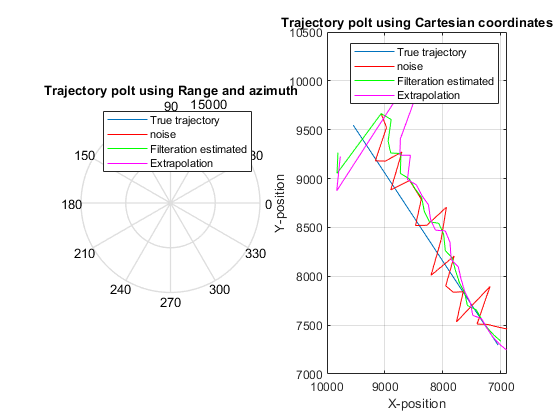

figure
subplot(1,2,1)
polar(beta,D)
hold on
polar(beta_m,D_m,'r')
polar(betai,Di,'g')
polar(betaiE,DiE,'m')
title('Trajectory polt using Range and azimuth')
legend('True trajectory','noise','Filteration estimated','Extrapolation')

subplot(1,2,2)
plot(X,Y); set(gca, 'XDir','reverse')
hold on
plot(X_m,Y_m,'r'); set(gca, 'XDir','reverse')
plot(xi,yi,'g'); set(gca, 'XDir','reverse')
plot(xiE,yiE,'m'); set(gca, 'XDir','reverse')
title('Trajectory polt using Cartesian coordinates')
xlabel('X-position')
ylabel('Y-position')
legend('True trajectory','noise','Filteration estimated','Extrapolation')
grid on

**Comment:** In the above figure, created trajectory, measurments and kalman filter estimations applying and not applying extrapolation with one step ahead were plotted in both cartesian and polar coordinates. It can be seen that our object moves around 3.5 kilometers toward the observerslightly shifting right and left around the track. It approaches the observer with an azimuth angle of ~ 43,44 degrees. The measurments sometimes came  too far away from the true trajecctory (difference in order of hunderds of meters). 

**Plotting errors**

**(a)** Errors of extrapolation and filtration estimates of range $D$ relative to $\sigma_{D\;}$.

**(b)** Errors of extrapolation and filtration estimates of azimuth $\beta$ relative to $\sigma_{\beta }$ .

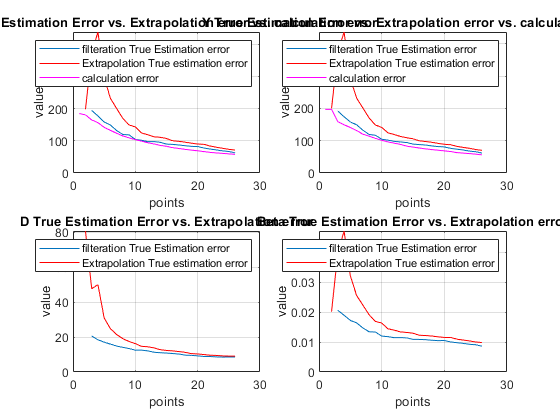

%Error plotting
figure
subplot(2,2,1)
plotErr(Errx,ErrxE,Px,'X')
subplot(2,2,2)
plotErr(Erry,ErryE,Py,'Y')
subplot(2,2,3)
plotErr(ErrD,ErrDE,NaN,'D')
subplot(2,2,4)
plotErr(Errbeta,ErrbetaE,NaN,'Beta')

**Comment:** From the graph above, we can see that  true errors of estimation in both X and Y coordinatedes are are following the calculation errors as the gap between them shrinks as the object approaches the observer. Both errors decrese with each time step, approaching a vlaue of ~60 m at the end of the 26 steps, which is smaller compared to the distance itself measured in Kilometerrs. Similarly, true  errors in range estimation (D) tends to decrease with getting further form the starting position and heading towards the observer, appraoching a value of ~8.7 at the end of steps, which is much better compared to the errors in single axis X or Y. The graph nearly turns linear at the last 12~13 points. Finally, The errors in azimuth estimation followed the same decreasing trend and was very small of values approaching to 0.01 rads (~0.57 degrees) at the end of steps.

11. Analyze dependence of coordinate x on azimuth β

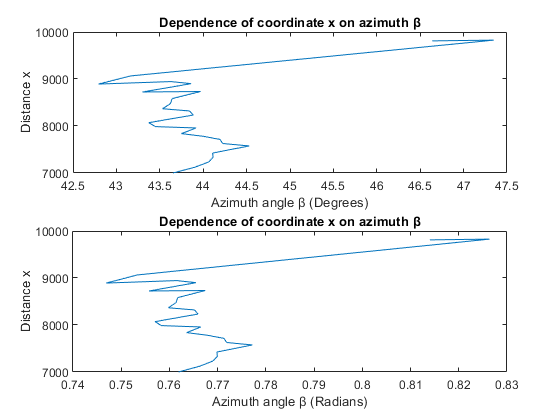

betai_degree  =  zeros(length(xi),1);
for i  =  1:length(xi)
    betai_degree(i)  =  rad2deg(betai(i));
end
%Plot dependence of coordinate x on azimuth β.
figure
subplot(2,1,1)
plot(betai_degree,xi)
title('Dependence of coordinate x on azimuth β')
xlabel('Azimuth angle β (Degrees)')
ylabel('Distance x')

subplot(2,1,2)
plot(betai,xi)
title('Dependence of coordinate x on azimuth β')
xlabel('Azimuth angle β (Radians)')
ylabel('Distance x')

**Comment:** The graph above shows clearly that cordinate position X dependance on the aximuth angle beta 

12. Calculate condition number of covariance matrix R over the observation interval.

13. Analyze filter gain K. Dimension of filter gain in this case is 4x2.

% Plot K(1,1)


14. Run filter again over M = 500 runs but use other initial conditions to generate a trajectory

Figure (1)


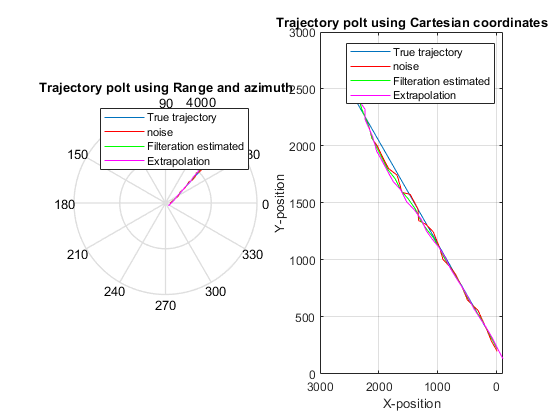

Figure (2)


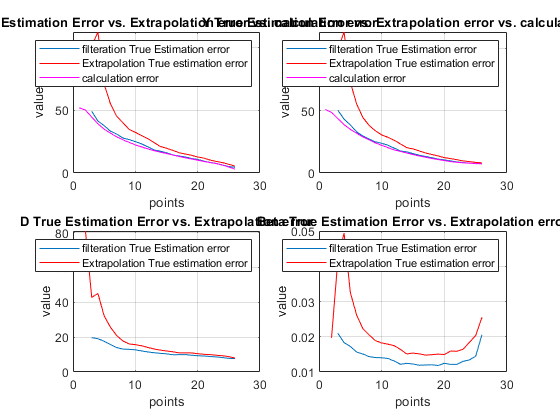

Figure (3)


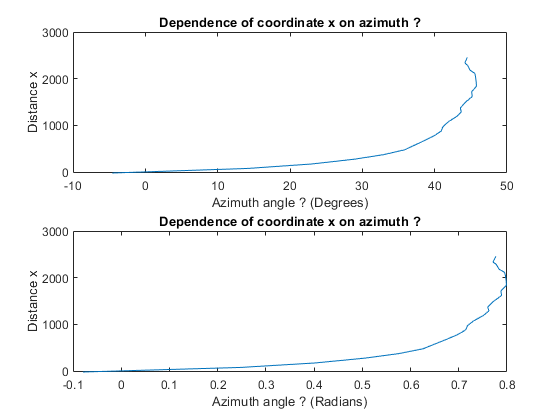

X1 = 3500/sqrt(2);      % X initial value
Y1 = 3500/sqrt(2);      % Y initial value
sigma_d1 = 20;               % Range measurements noise standard deviation
sigma_beta1 = 0.02;          % Azimuth measurements noise standard deviation

HW10_M_runs(M,X1,Y1,sigma_d1,sigma_beta1)

**Comment:**

In figure 1, created trajectory, measurments and kalman filter estimations applying and not applying extrapolation with one step ahead were plotted in both cartesian and polar coordinates.  It can be seen that using these intila conditions those are much closet to the observer, our object moves around 3.53 kilometers toward the observer till it reaches him. The measurments are slightly shifting right and left around the track and this shift even reduces as the objecct approaches the observer. It approaches the observer with an azimuth angle of ~ 44.5 degrees. overall, it looks much close to the true track than the previous case when the measuremts usually went hundered of memters off teh true track. 

In Figure 2, we can see that  true errors of estimation in both X and Y coordinatedes are are following the calculation errors as the gap between them shrinks as the object approaches the observer. Both errors decrese with each time step, approaching a vlaue of ~5 m at the end of the 26 steps, which is very small compared to the distance itself measured in Kilometerrs and even compared the previous case with further initial points giving an error of ~60 m. Similarly, true  errors in range estimation (D) tends to decrease with getting further form the starting position and heading towards the observer, appraoching a value of ~8 at the end of steps, which is much better compared to the errors in single axis X or Y, but not much less than the previous case with the further initial points**.!!!!!!!!!!!!!!!!!!!!** Also, the graph nearly turns linear at the last 12~13 points. Finally, The errors in azimuth estimation followed the same decreasing trend and was very small of values approaching to 0.014 rads (~0.57 degrees) until the 17th steps then started rising again. **!!!!!!!!!!!!!!!!**

In Figure 3, we can clearly see  that cordinate position X dependance on the azimuth angle beta can be assumed linear for small angles(beta less than 15 degrees). Because, sin(beta) is nearly equal to beta itself in this region. Also, as beta increases, the relation slightly turns into nonlinear but still acceptable and the linearization errors could be neglected until beta reaches 30 degreees. After that it loses its nonlinearity and it is very importatnt in this case to take the liearity errors into consideration. 

**18.** Make conclusions how linearization errors affect tracking accuracy and how important for tracking accuracy is starting position of a moving object (close or far from an observer).

**Conclusion:** 

Clearly, from the two previous cases, as we approach the observe, errors decrease. this was very clear in the error values in the second case with the closer initial position, which were way smaller than the first case with the furthet initial position. **continue**

19. Run filter again over M = 500 runs but use other initial conditions to generate a trajectory and other values of variances of measurment noises to generate polar measurments

Figure (1)


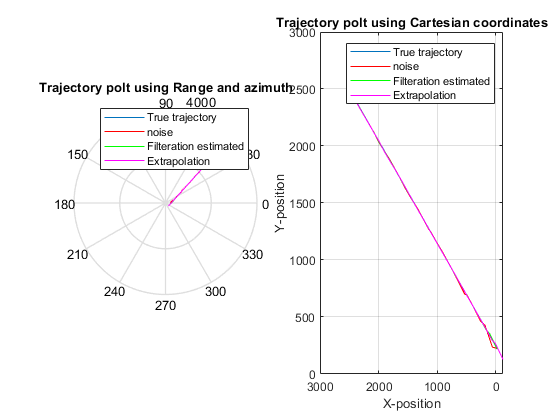

Figure (2)


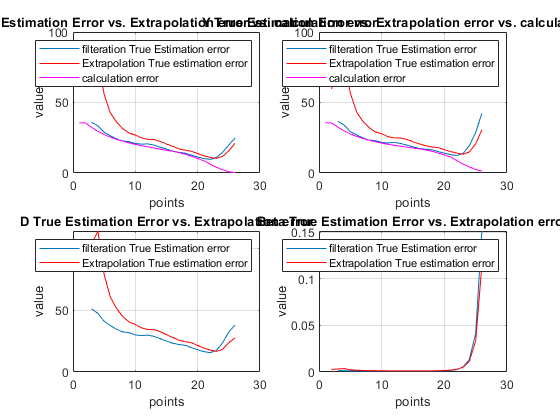

Figure (3)


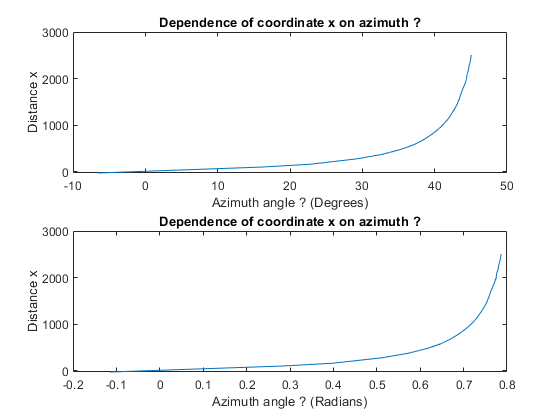


X1 = 3500/sqrt(2);      % X initial value
Y1 = 3500/sqrt(2);      % Y initial value
sigma_d1 = 50;               % Range measurements noise standard deviation (2.5 times larger than previous one)
sigma_beta1 = 0.0015;          % Azimuth measurements noise standard deviation (13 times  smaller than previous one)

HW10_M_runs(M,X1,Y1,sigma_d1,sigma_beta1)

**Comment:**

In figure 1, all the graphs totally alligns with the true data, mainly because our azimuth measurements noise standard deviation is very small. So, the distance measurments might come even larger than previous because we increased tje range measurments standrard deviation; however, the object will still be aligned with the true trajectory. Our navigation system actually is blind in this case and can be tricked with this alignment with the true data.

In Figure 2, we can see that  true errors of estimation in both X and Y coordinatedes are **!!!!!!!!!!!!!!.** Similarly, true  errors in range estimation (D) tends to decrease with getting further form the starting position and heading towards the observerhowever, this time was much greater than the previous ccase mainly because we increased the range measurments standrard deviation. It is appraoching a value of ~16 at the end of steps. Also, it rises up again at the end because it reached the observer and then kept moving forward getting away from him. Finally, The errors in azimuth estimation is very small as expected for most of the trajectory but then rised dramatically at the end of steps just because  after it passes by the observer, instantly, 180 degrees are added to them. **(modify this ????????????????)**

In Figure 3,the realtion is similar to the previous case but the curve is much sommtherat the range of higher angles. **!!!!!!!!!!!!!!!!!!!!**

21. Make final conclusions under which conditions navigation system may become blind and filter may diverge. Which factors has the greatest influence? Linearization errors or ill-conditioned problem? Which solution can help to overcome this particular ill-conditioned problem?